# Actividad 1.12 (Modelado Cinemático de Piernas)

Fernando Estrada Silva // A01736094

**1. Obtener** la matriz de  transformación **homogénea T **de los siguientes sistemas la cual relacione la posición y orientación del extremo del robot respecto a su sistema de referencia fijo (la base).

**2. Implementar** el código requerido para generar el cálculo de las matrices **homogéneas (H1, H2, H3, etc.)** y la matriz de **transformación (T)** de cada sistema. Simulando cada una de las transformaciones desde la trama absoluta hasta la trama final.

**Sistema 1. **

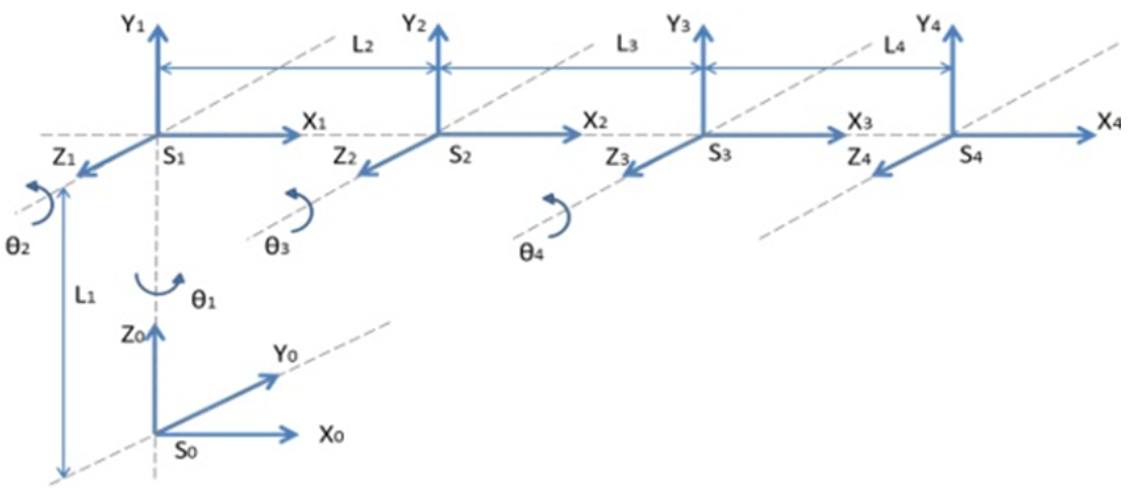

Dentro del codigo, H1 aplica una rotación de 90 grados alrededor del eje x y una traslación de 4 unidades en el eje z. La función `rotx(pi/2)` crea una matriz de rotación en torno al eje x

De forma similar, H1, H2 y H3, son matrices de transformación que aplican una traslación de 1.33 unidades en el eje x. Cada una de estas matrices representa una traslación pura sin rotación.

Para aplicar las transformaciones, se obtiene el producto de matrices, dando como resultado la matriz de transformación global. 

Finalmente, *x,y,z* son arreglos que representan las coordenadas de la estructura de translación y rotación en el espacio tridimensional. Aquí, las coordenadas definen tres puntos en el espacio para posteriormente graficar sobre tales medidas. 

H0 =SE3; % Punto de origen
H1=SE3(rotx(pi/2), [0 0 4]); % Rotar en x 90 grados positivos y traslación en z
H2=SE3([1.33 0 0]); % Traslación en x
H3=SE3([1.33 0 0]) % Traslación en x
H4=SE3([1.33 0 0]) % Traslación en x

H20= H1*H2;
H30= H20*H3 %Matriz de transformación homogenea global de 3 a 0 
H40= H30*H4

%Coordenadas de la estructura de translación y rotación
x=[4 0 0];
y=[0 0 0];
z=[4 4 0];

**Resultado Obtenido **

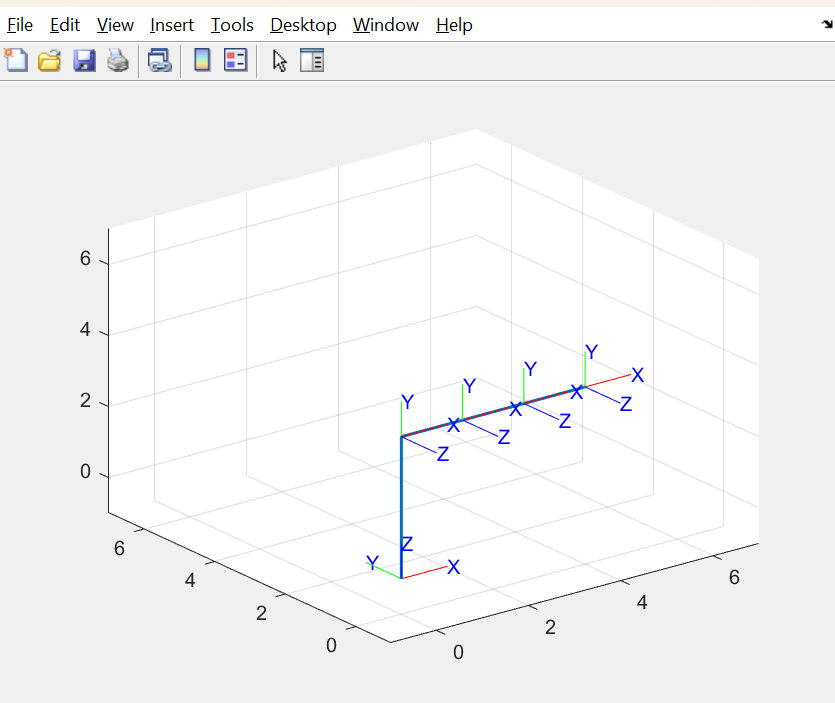

**Sistema 2.**

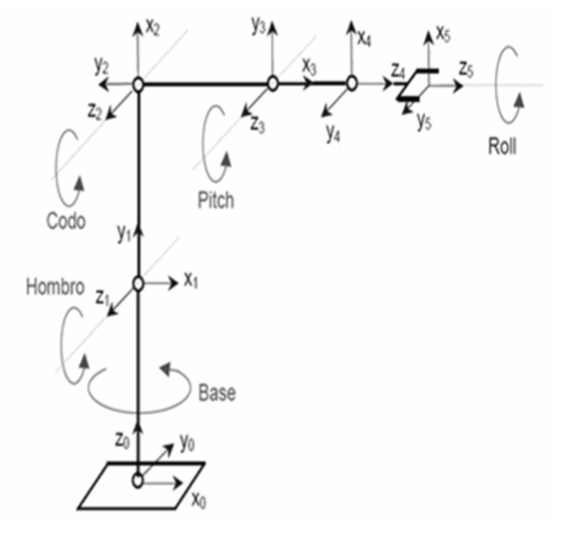

De manera similar se obtiene el segundo esquema, modificando las rotaciones sobre distintos ejes y el escalar de traslación. 

El sistema cuenta con 5 movimientos, tanto de rotación como traslación de forma simultánea. Se ha considerado una escala de -1 a 10 para hacer el cambio más notorio. 

H0=SE3;
H1=SE3(rotx(pi/2), [0 0 5]);
H2=SE3(rotz(pi/2), [0 5 0]);
H3=SE3(rotz(-pi/2),[0 -3.3 0]);
H4=SE3(rotz(pi/2)*rotx(pi/2), [3.3 0 0]);
H5=SE3([0 0 3.3]);

H20= H1*H2;
H30= H20*H3;
H40= H30*H4;
H50= H40*H5;

x=[10 0 0];
y=[0 0 0];
z=[10 10 0];

plot3(x, y, z,'LineWidth', 1.5); axis([-1 10 -1 10 -1 10]); grid on;
hold on;



**Resultado obtenido **

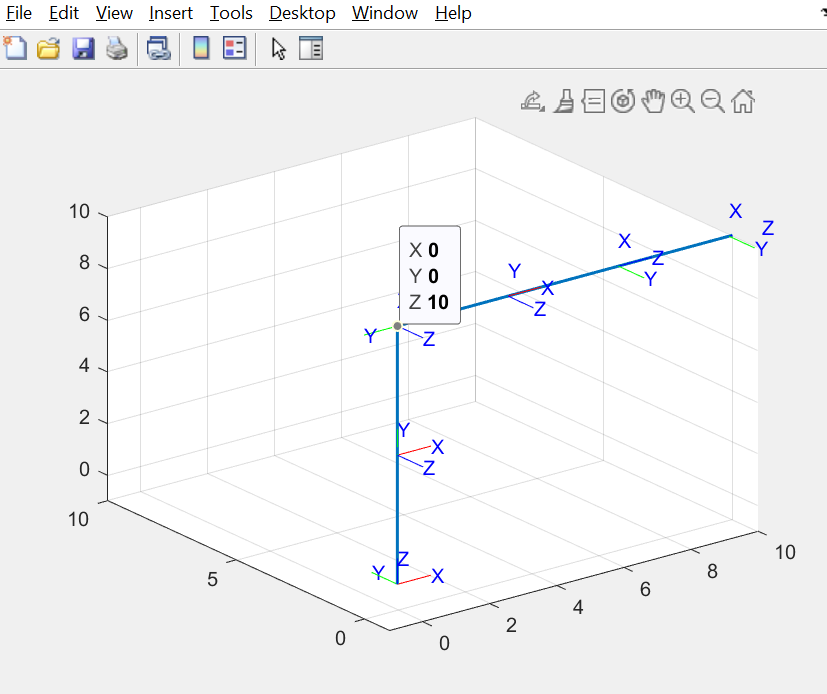

**Sistema 3.  **

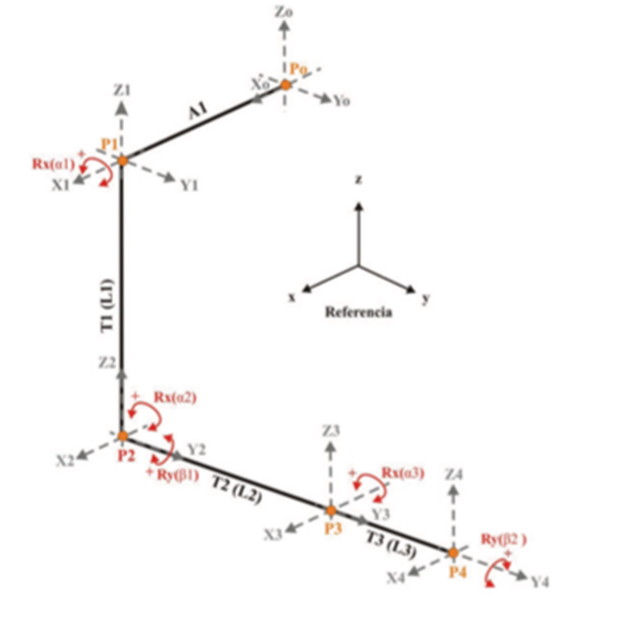

Finalmente para este ultimo sistema, se ha modificado la posición inicial y el sentido en que se realizan los movimientos. Como se puede apreciar, el sistema no inicia desde el origen, sino desde un punto ya trasladado, por lo que el movimiento cambia, pero en escencia el programa funciona de la misma manera. 

H0=SE3([0 3 3]);
H1=SE3(rotz(-pi/2), [0 3 3]);

H2=SE3([3 0 0]);
H3=SE3([0 0 -3]);
H4=SE3([0 1 0]);
H5=SE3([0 1 0]);

H20= H1*H2;
H30= H20*H3;4
H40= H30*H4;
H50= H40*H5;

x=[0 0 0 3];
y=[3 0 0 0];
z=[3 3 0 0];

plot3(x, y, z,'LineWidth', 1.5); axis([-1 3 -1 3 -1 3]); grid on;
hold on;


**Resultado obtenido **